# GGV Map simとGGV 実車の比較

### 実車ロガーデータ

filename = 'nit23_AutoX_ASE_kawai.xlsx';

logdata = readmatrix('nit23_ASE_AutoX_kawai.xlsx', 'Range', 'C16');

rad = 0.23;
Rz = [cos(rad) -sin(rad); sin(rad) cos(rad)];

logdata_rot = zeros(length(logdata), 3);

for i = 1:length(logdata)
    logdata_roti = Rz*[logdata(i,1);logdata(i,2)];
    logdata_rot(i,:) = [logdata_roti(1,1),logdata_roti(2,1),logdata(i,3)];
end

ax_car = -logdata_rot(:,1);
ay_car = -logdata_rot(:,2);
v_car = logdata_rot(:,3);

### GGV Map 

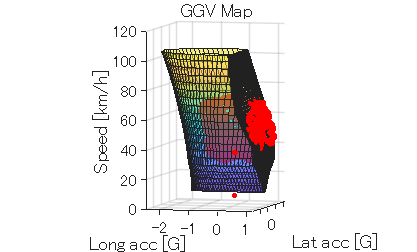

% ggv map
load("GGV_map_nit23_50.mat");
surf(GGV(:,:,2),GGV(:,:,1),GGV(:,:,3),'FaceAlpha',0.5)
hold on;

% plot3(x, y, z, マーカー設定)
plot3(ay_car, ax_car, v_car, 'ro', 'MarkerSize', 2, 'MarkerFaceColor', 'r');
hold on;

title('GGV Map')
xlabel('Lat acc [G]')
ylabel('Long acc [G]')
zlabel('Speed [km/h]')
view(105,5)
set(gca,'DataAspectRatio',[1 1 20])